# Cough-Signal Based COVID Detection Model 

BME 3053C Group Project MATLAB Header and Live Script

Group Members:Jasmine Day, Zinia Basil, Ahmet Bilgili

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

April 12, 2021

Description: With the start of the COVID-19 pandemic, individuals were scrambling to get tested and verify whether or not they have been infected with the SARS-CoV-2 virus. Although virus screening and contact tracing methods have become more prevalent, these are simply superficial methods of detecting whether or not an individual has COVID-19 with no direct level of confidence. With no significant, accurate, or cost-effective method of testing from home being available, our team focuses on proposing a method to combat this. The broad scope of our project is to use machine learning to be able to detect within a range of accuracy whether or not an individual has been infected with COVID-19. Our project is based around the variations of signal frequencies in cough recordings between healthy and COVID-19 patients. Recording a cough noise to feed into an algorithm is a cost-effective and efficient method of offering a general wide range use test for potentially infected patients to have some degree of certainty around their health status. We are achieving this through the utilization of decision tree and support vector machine to train a model that can be used to predict potential COVID-19 patients based on signal variations of their coughs. 

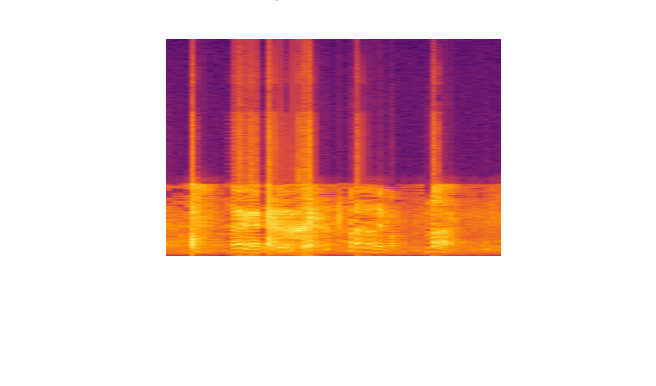

clc;clear;
% load data 
[train_x, train_y, test_x, test_y, classes] = load_data;
data = [train_x, train_y; test_x, test_y];
% visulization of the data 

imshow('_-_5kbw2Mcw_ 0000_ 10000.png')
title("Example Mel Spectograms of one ofthe participants")

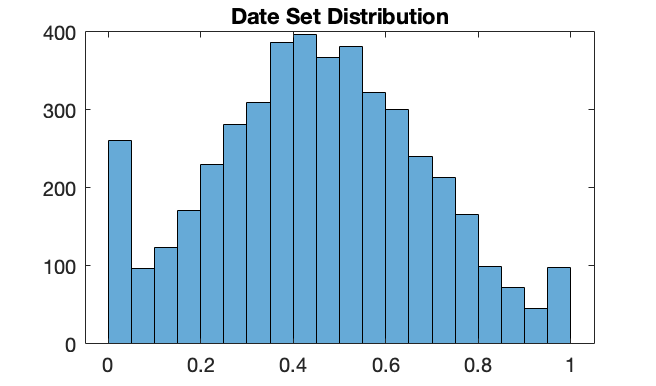


histogram(data)
title('Date Set Distribution')

## Decision Tree Model 

% Train the decision tree model using cross validation 
dt = fitctree(data(:,1:26), data(:,27), 'CrossVal','On')

dt =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'}
           ResponseName: 'Y'
        NumObservations: 169
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


% predict the labels 
dtClass = kfoldPredict(dt)

dtClass =      0
     0
     0
     1
     1
     0
     1
     1
     1
     0


% Compute the kfold loss 
dtResubErr = kfoldLoss(dt)

dtResubErr = 0.1183

% Compute the accuracy of the model 
accuracy = sum(dtClass == data(:,27))/length(data(:,27)) 

accuracy = 0.8817

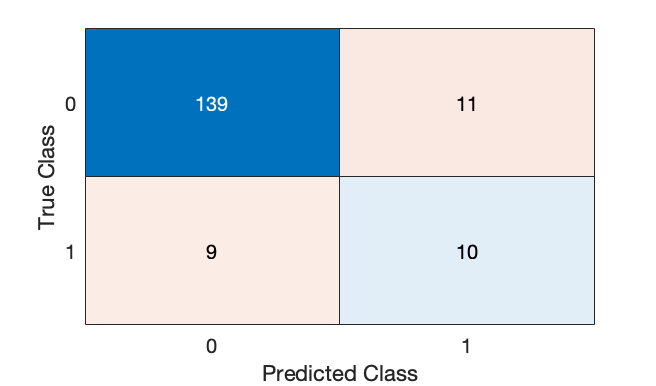

deResubCM =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


% confusion matrix 
deResubCM = confusionchart(data(:,27),dtClass)

## SVM Model 

% Train binary classification model of SVM 
SVMModel = fitcsvm(data(:,1:26), data(:,27))

SVMModel =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 169
                    Alpha: [43×1 double]
                     Bias: 0.8048
         KernelParameters: [1×1 struct]
           BoxConstraints: [169×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [169×1 logical]
                   Solver: 'SMO'


  Properties, Methods


% Using cross validation 
SVMMdl = crossval(SVMModel)

SVMMdl =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'}
           ResponseName: 'Y'
        NumObservations: 169
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


% Class labels; 0 represents non-COVID patient and 1 represents COVID
% patient
classOrder = SVMModel.ClassNames 

classOrder =      0
     1


% predicting the label of the test set 
label = kfoldPredict(SVMMdl)

label =      0
     0
     0
     0
     1
     0
     0
     1
     0
     0


% calculating the accuracy of the model 
accuracy = sum(label == data(:,27))/length(data(:,27))

accuracy = 0.9349

% resubstitution error 
svmResuberror = kfoldLoss(SVMMdl)

svmResuberror = 0.0651

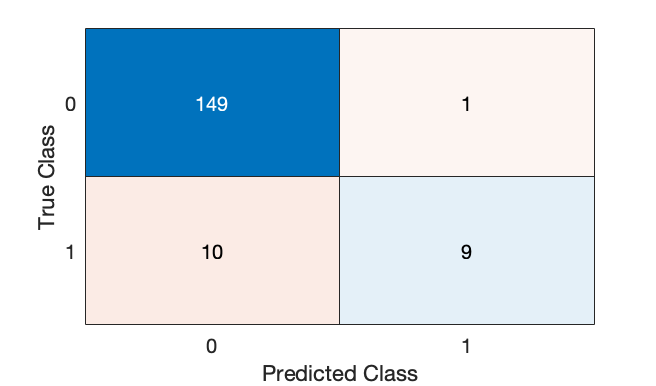

% confusion matrix 
confusionchart(data(:,27),label)